e = 0.1;
char_star = load_charecteristic_values_Earth();
a = char_star.l + 950;
r = @(E) a * (1 - e * cos(E));

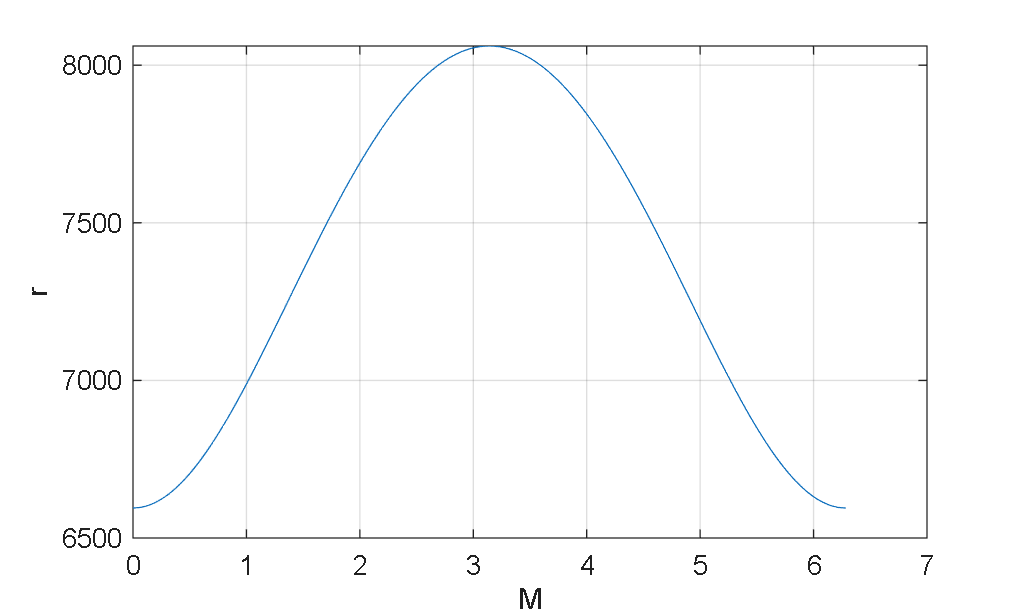

M = linspace(0, 2 * pi, 1000);
E = mean_to_eccentric_anomaly(M, e);
figure
plot(M, r(E))
grid on
xlabel("M")
ylabel("r")

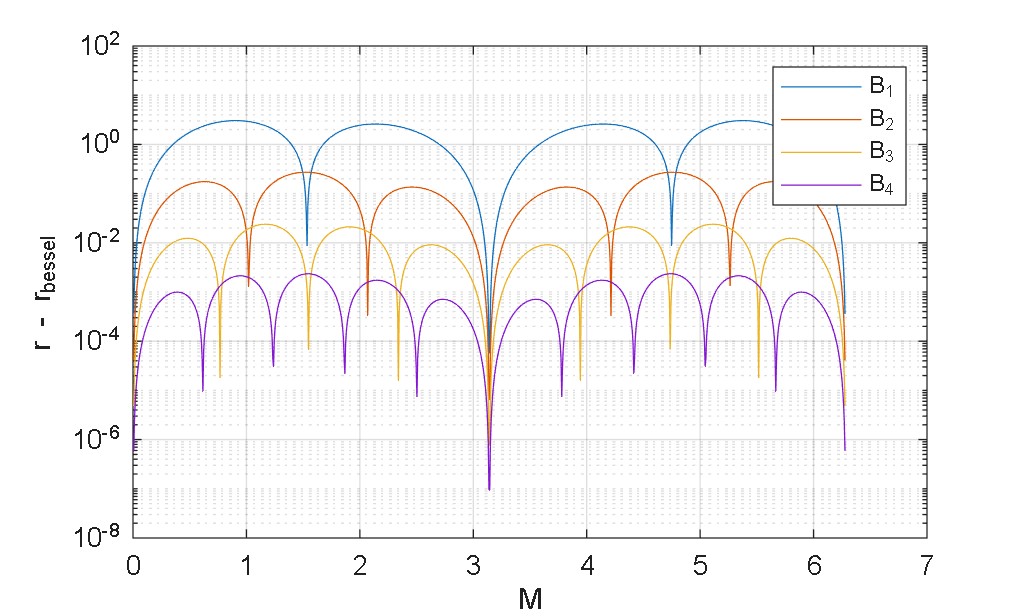

E_bessel_1 = M + 2 * besselj(1, e) * sin(M);
E_bessel_2 = M + 2 * besselj(1, e) * sin(M) + besselj(2, 2 * e) * sin(2 * M);
E_bessel_3 = M + 2 * besselj(1, e) * sin(M) + besselj(2, 2 * e) * sin(2 * M) + 2 / 3 * besselj(3, 3 * e) * sin(3 * M);
E_bessel_4 = M + 2 * besselj(1, e) * sin(M) + besselj(2, 2 * e) * sin(2 * M) + 2 / 3 * besselj(3, 3 * e) * sin(3 * M) + 1 / 2 * besselj(4, 4 * e) * sin(4 * M);
figure
plot(M, abs(r(E) - r(E_bessel_1))); hold on
plot(M, abs(r(E) - r(E_bessel_2)))
plot(M, abs(r(E) - r(E_bessel_3)))
plot(M, abs(r(E) - r(E_bessel_4)))
yscale("log")
grid on
xlabel("M")
ylabel("r - r_{bessel}")
legend("B_1", "B_2", "B_3", "B_4")

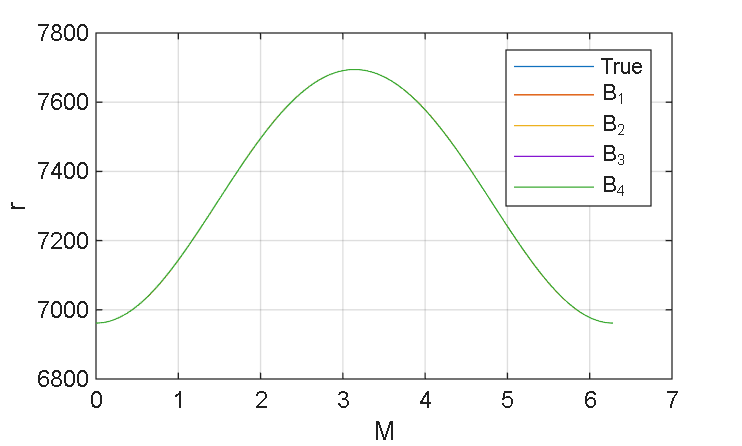

figure
plot(M, r(E)); hold on
plot(M, r(E_bessel_1));
plot(M, r(E_bessel_2));
plot(M, r(E_bessel_3));
plot(M, r(E_bessel_4));
grid on
xlabel("M")
ylabel("r")
legend("True", "B_1", "B_2", "B_3", "B_4")